averaging IIR/FIR first order filter design, frequency rget the bode plot of the transfer function of the averaging FIR filter esponse and simulink simulation

Fs=2*8e3; % sampling frequency
Fc=170; % cutoff frequency
alpha=1-2*pi*Fc/Fs;
nb=round(log2(1/(1-alpha))); % number of shift to the right correspending to multiplication by alpha
NbPoints=10000;
Ndec=round(log10(Fs/2));
Fstart=1;
i=1:Ndec*NbPoints 

i =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


freq=(Fstart*10.^(i/NbPoints))

freq = 	1.0e+04 *

    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


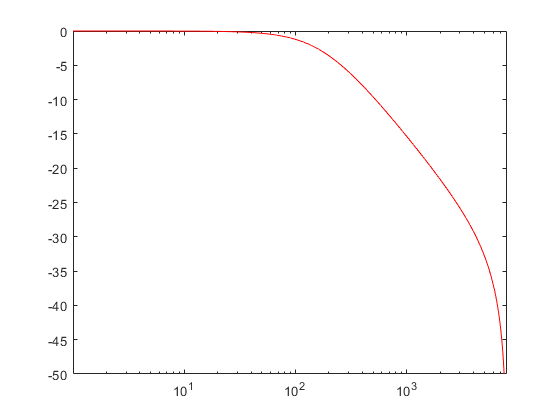

%freq=1:1:Fs/2;
H_f=(1-alpha)*cos(pi*freq/Fs)./sqrt(1+(alpha^2)-2*alpha*cos(2*pi*freq/Fs));
MagH=abs(H_f);
PhaseH=angle(H_f)*360/(2*pi);
semilogx(freq,20*log10(MagH),"Color",'r')
ylim([-50,0])
xlim([0,Fs/2])

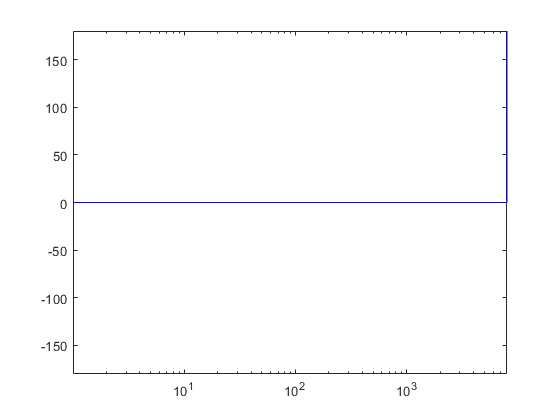

semilogx(freq,PhaseH,"Color",'b')
ylim([-180,180])
xlim([0,Fs/2])